# 2023-24-ex-final-q1

# P1

Consider the following problem on $[0,L]$ given by the equaiton


$$-\frac{\mathrm{d}}{\mathrm{d} x}\left(k(x)\frac{\mathrm{d} u}{\mathrm{d} x}\right) = 0, \qquad 0 < x < L$$


where $L > 0$ and $k = k(x)$ is a function which is constant and equal to $k_{1}$ on $\Omega^{1} = [0, h_{1})$ and constant and equal $k_{2}$ on 

$\Omega_{2} = [h_{1}, h_{1} + h_{2}]$ with $L = h_{1} + h_{2}$. Assume the following boyundary conditions.


$$u(0) = u_{0},\qquad \left.k(x)\frac{\mathrm{d}u}{\mathrm{d}x} + 20\left( u(x) - 50\right)\right|_{x = L} = 0,$$


with $k_{1} = 10$, $k_{2} = 20$ and $u_{0} = 200$.

We will solve the one-dimensional problem by means of linear elements at $\Omega^{1}$ and another at $\Omega^{2}$.

# 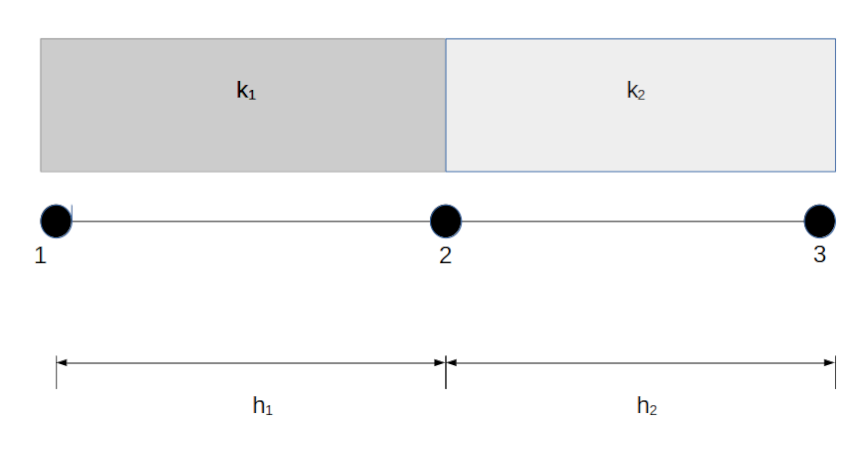

clearvars
close all

global k numNodes elem numElem

%Data
k = [10.0, 20.0];
h = [0.10, 0.20];      
hHint = [0.20, 0.10];   
U1 = 200.00;            
UInf = 50.00;           
beta = 20.00;           

elem = [1, 2;
    2, 3];              %Connectivity matrix

numElem = size(elem, 1);
numNodes = numElem + 1; %Linear elements!


## Part (a)

(a) (3 points) Let $K$ be the stiffness matrix of the global problem, Which is the value of $K_{2,2}$ when $h_{1} = 0.1$ and $h_{2} = 0.2$?

- 3.0000e+02

- Leave it empty (no penalty) 

- 2.5000e+02

- 1.5000e+02

-  2.0000e-02 ✅

**Hint. **For $h_{1} = 0.2$ and $h_{2} = 0.1$ this value is $K_{2,2} = 250.0$

#### Solution:

Here $a_{1} (x) = k(x)$ and $a_{0}(x) = 0$ for all $0 x < L$. So the stiffness matrices of the elements $\Omega^{1}$ i $\Omega^{2}$ are, respectively,

$K^{1,1} = \frac{k_{1}}{h_{1}}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right) = 100\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right),\quad 
K^{2,1} = \frac{k_{2}}{h_{2}}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right) = 100\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right)$,

($k_{1} = 10.0$, $k_{2} = 20.0$;  $h_{1} = 0.1$, $h_{2} = 0.20$). Hence, the assembled stiffness matrix is:

$K = 100\left(\begin{array}{rrr}
1 & -1 & 0\\
-1 & 2 & -1\\
  0  & -1 & 1
\end{array}\right)$,

and therefore $K_{2,2} = 200.0$

**Hint. **Indeed, for these values of $h_{1}$, $h_{1} = 0.20$, and $h_{2}$, $h_{2} = 0.10$, the siffness matrices of the elements $\Omega_{1}$ and $\Omega_{2}$ are respectively, 

$K^{1,1} = \frac{k_{1}}{h_{1}}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right) = 200\left(\begin{array}{rr}
1/4 & -1/4 \\
-1/4 & 1/4\end{array}\right),\quad 
K^{2,1} = \frac{k_{2}}{h_{2}}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right) = 200\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right)$,

So the corresponding assembled (global) stiffness matrix is

$K = 200 \left(\begin{array}{rrr}
-1/4 & 1/4 & 0\\
-1/4 & 5/4 & -1\\
  0  & -1 & 1
\end{array}\right)$;

and hence $K_{2,2} = 250.0$

%Data
i = 2; j = 2;
K = stiffnessMatrix(h); 
KHint = stiffnessMatrix(hHint); 
fprintf(['for h1 = %.2f, h2 = %.2f, K(%d,%d) = %.4e\n',...
    'Hint. For h1 = %.2f, h2 = %.2f, K(%d,%d) = %.4e\n'],...
    h, i, j, K(i,j), hHint, i, j, KHint(i,j))

for h1 = 0.10, h2 = 0.20, K(2,2) = 2.0000e+02
Hint. For h1 = 0.20, h2 = 0.10, K(2,2) = 2.5000e+02


## Part (b)

(b) (5 points) Assuming $h_{1} = 0.1$ and $h_{2} = 0.2$, find the approximation $U_{3}$ of the solution $u(L)$.

- 1.4375e+02

- Leave it empty (no penalty)

- 1.6538e+02

- 1.5714e+02 ✅

- 1.5000e+02

**Hint: **$Q_{3}$ satisfies the equation $Q_{3} + 20\left(U_{3} - 50\right) = 0$.

#### Solution:

The assembled system is


$$100\left(\begin{array}{rrr}
1 & -1 & 0\\
-1 & 2 & -1\\
0 & -1 & 1\end{array}\right) 
\left(\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}
\end{array}\right) = \left(\begin{array}{c}
Q_{1}\\
Q_{2}\\
Q_{3}\end{array}\right) +
\left(\begin{array}{c}
F_{1}\\
F_{2}\\
F_{3}\end{array}\right) 
$$


Here with $F_{1} = F_{2} = F_{3} = 0$, since the r.h.s. of the equation is $f(x) = 0$ for all $0 < x < L$.

Boundary conditions,

- Natural B.C.: $Q_{2} = 0$, $Q_{3} = \left. k(L)\frac{\mathrm{d} u}{\mathrm{d} x}(L) = -20\left(u(L) - 50\right) = -20\left(U_{3} - 50)$

- Essential B.C.: $U_{1} = u(0) = u_{0} = 200$

Therefore, the reduced system casts, in matrix notation


$$100\left(\begin{array}{rr}
2 & -1\\
-1 & 1\end{array}\right)\left(\begin{array}{c} U_{2} \\ U_{3}\end{array}\right) = \left(\begin{array}{c}
Q_{2} = 0\\
-20\left(U_{3} - 50\right)\end{array}\right) 
- 100\left(\begin{array}{r}
-1\\
0\end{array}\right)\left(U_{1} = 200\right) + \left(\begin{array}{c} F_{1} = 0\\ F_{2} = 0
\end{array}\right)$$


or, equivalently,

$\left\{\begin{array}{lcl}
\: \: \:200 U_{2} - 100 U_{3}  =  20000\\
-100U_{2} + 120U_{3}  = -20 U_{3} + 1000
\end{array}\right\}\Longleftrightarrow
\left\{\begin{array}{lr}
 2U_{2} - U_{3} = 20000\\
-U_{2}+ 1.2 U_{3} = 1000
\end{array}\right\}$.

Solving this last system by Cramer's rule, yields


$$U_{2} = \frac{
\left|\begin{array}{rr}
200 & -1 \\
10 & 1.2
\end{array}\right|
}
{
\left|
\begin{array}{rr}
2 & -1\\
-1 & 1.2
\end{array}
\right|
} = \frac{240 + 10}{2.4 -1} = \frac{250}{1.4} = 178.5714,\quad
U_{3} = \frac{
\left|\begin{array}{rr}
2  & 200\\
-1 & 10
\end{array}\right|
}
{
\left|
\begin{array}{rr}
2 & -1\\
-1 & 1.2
\end{array}
\right|
} = \frac{20 + 200}{2.4 -1} = \frac{220}{1.4} = \frac{1100}{7} = 157.1429,\qquad
$$


Thus, finally: $u(L)\approx U_{3} =$1.571429e+02.

%Boundary conditions

%Natural BC
Q = zeros(numNodes,1);
K(3,3) = K(3,3) + beta;
Q(3) = beta*UInf;

%Essential BC
u = zeros(numNodes, 1);
fixedNodes = 1;
freeNodes = setdiff(1:numNodes,fixedNodes);
u(1) = U1;

%Reduced system
Fm = Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

%Solve the reduced system
um = Km\Fm;

%Add the values of the temperature at the free node to the global vector
%solution
u(freeNodes) = um;

fprintf(['Assuming h1 = %.2f and h2 = %.2f, the approximation U3 of the solution u(%.2f) is U3 = %.4e\n',...
    'Hint. The approximation U2 of the solution u(%.2f) is U2 ≈ %.4e\n'], h, h(1)+h(2),u(3),h(1),u(2))

Assuming h1 = 0.10 and h2 = 0.20, the approximation U3 of the solution u(0.30) is U3 = 1.5714e+02
Hint. The approximation U2 of the solution u(0.10) is U2 ≈ 1.7857e+02


## Part (c) 

(c) (2 points) Now suppose that $h_{1} = h_{2} = L/2$. Give the value of $L = h_{1} + h_{2}$ so that $U_{3} = 120$.

- 7.6190e-01✅

- Leave it empty (no penalty)

- 6.6667e-01

- 3.3333e-01

- 1.0000e-01

#### Solution:

Now $h_{1} = h_{2} = L/2$, and the local stiffness matrices are,

$K^{1,1} = \frac{k_{1}}{h_{1}}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right) = \frac{2k_{1}}{L}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right),\quad 
K^{2,1} = \frac{k_{2}}{h_{2}}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right) = \frac{2k_{2}}{L}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1\end{array}\right)$,

whereas the global system is

$\left(\begin{array}{rcr}
k_{1} & -k_{1} & 0\\
-k_{1} & k_{1} + k_{2} & -k_{2}\\
0 & -k_{2} & k_{2}
\end{array}\right)
\left(\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}\end{array}
\right)
=\frac{L}{2} \left(\begin{array}{l}
Q_{1}\\
Q_{2} = 0\\
Q_{3} =-20\left(U_{3} - 50\right)
\end{array}\right)$,

where we've alredy set the natural B.C. (i.e. $Q_{2} = 0$, $Q_{3} = -20(U_{3}-50)$). As in the previous question, $U_{1} = u_{0} = 200$ is the essential boundary conditon to take into account. We want to find th lenght $L$ such that $U_{3} = 120$. Bearing this in mind, if follows at once that the above linear system can be re-arranged to yield the reduced system 

$\left(\begin{array}{cc}
k_{1} + k_{2} & 0 \\
-k_{2}  & 20(U_{3} - 50)
\end{array}\right)
\left(\begin{array}{c}
   U_{2}\\
   L/2
\end{array}\right) = \left(\begin{array}{cr}
k_{1} & k_{2}\\
   0 & -k_{2}
\end{array}\right)
\left(\begin{array}{c}
U_{1} = 200\\
U_{3} = 120
\end{array}\right)$,

that have $U_{2}$ and $L/2$ as unknowns. As $k_{1} = 10$, $k_{2} = 20$, when we substitute this values, the system to solve is

$\left(\begin{array}{rr}
30 & 0\\
-20 & 1400
\end{array}\right)
\left(\begin{array}{c}
U_{2}\\
L/2
\end{array}\right) =
\left(\begin{array}{r}
   4400\\
-2400
\end{array}\right)$.

As this is a lower triangular linear system, we can solve it by forward substitution to get,


$$\begin{array}{rcl}
     U_{2} &\!\!\!\!\!\!\!\!\!=\!\!\!\!\!& \frac{440}{3} =146.\overline{6},\\
     L &\!\!\!\!\!\!\!\!\!\!\!=\!\!\!\!\!\!& \frac{-2400 + 20 U_{2}}{700} = \frac{-2400 + 20\frac{440}{3}}{700} = 
               \frac{-72 + 88}{21} = \frac{16}{21} = 0.\overline{761904}.
\end{array}$$


Hence, the length is $L=$ 7.61904e-01.

U3 = 120.0; 
Km = [k(1) + k(2), 0;
    -k(2), beta*(U3-UInf)];
Fm = [k(1); 0]*U1 + [k(2); -k(2)]*U3;

x = Km\Fm;
fprintf('If h1 = h2 = h, the value of L s.t. U3 = 120 is L = %.4e\n', 2*x(2))

If h1 = h2 = h, the value of L s.t. U3 = 120 is L = 7.6190e-01


function K = stiffnessMatrix(h)
    global k numNodes elem numElem
    K = zeros(numNodes);
    for e = 1:numElem
        Ke = k(e)*[1, -1; -1, 1]/h(e);
        rows = [elem(e,1); elem(e,2)];
        cols = rows;
        K(rows, cols) = K(rows, cols) + Ke;
    end
end